# Plotting Course 2021

Authored by Jaron Ma and Sean Koyama

This is a MATLAB Live Script, which is similar to a Jupyter Notebook in that it combined coding blocks with text/image annotations.

## Basic Plotting

    As a brief refresher, MATLAB is basically designed to create, manipulate, and plot matrices of data, which are sometimes considered vectors/arrays/tables. If you've used MATLAB before, the script below should look pretty familiar:

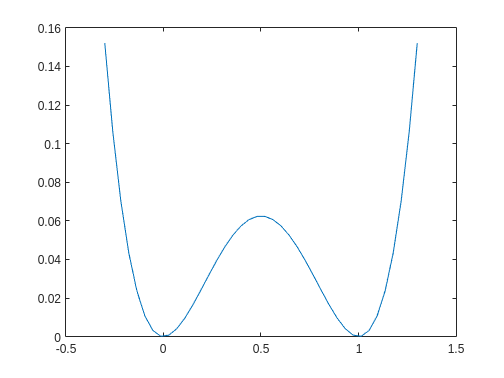

close all
clear all
x = linspace(-0.3,1.3,40);
y = x.^2 .* (1 - x).^2;
plot(x,y)

The plot command expects as a bare minimum an input in the form of a *1 x n* or *n x 1* vector of data. If there are two inputs of equal size, the first is interpreted as the x-coordinates of the data, and the second is interpreted as the y-cooridnates of the data, with the datapoints connected by a line in the order that they appear.

## Beyond the default

    The default output from plot is not bad on its own: The blue color of the plot used is pleasant, and the axis limits are scaled to the data. This makes it easy to get in the habit of falling back on the defaults, but our first tip for plotting is to be aware of how easy it is *not* to use the default settings. An equivalent command as above would have been:

plot(x,y,'Marker','none','Color',[0 0.4470 0.7410],'LineStyle','-','LineWidth',0.5)

Here, we are using **name-value** pairs. The properies named Marker, Color, etc., can be listed followed by the values you want them to take on. The values given above correspond to the default values chosen by MATLAB (as of R2021b), which makes it clearer how to change the plot's apperance. For example, to mix things up:

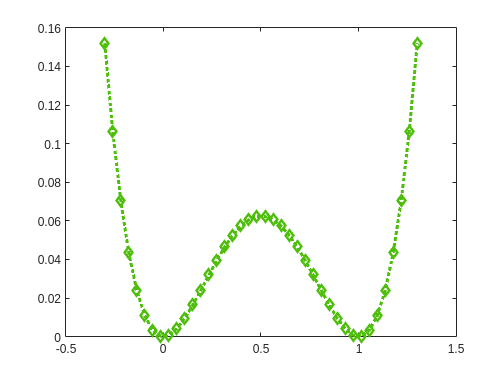

plot(x,y,'Marker','diamond','Color',[0.3 0.7470 0.0410],'LineStyle',':','LineWidth',2.5)

## Getting and Setting

    The next tip we have will further help customize your plots: consider taking the time to retain your object handles so that you can **get and set** properties in the code itself.

fig_1 = figure; 
ax_1 = axes(fig_1);
lin_1 = plot(ax_1,x,y);
set(lin_1,'Marker','diamond','Color',[0.3 0.7470 0.0410],'LineStyle',':','LineWidth',2.5)

The code above does a few things: It initializes a figure object and stores the handle as fig_1l it places an axes object inside the figure handle identified by fig_1, and it places a line plot on the axes handle identified by ax_1. By storing the object handles as variables, you can go back and use the set command to change the properties after the fact. You can use the get command to print out a list of all of the available properties for a given object:

get(lin_1)

    AlignVertexCenters: off
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: off
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: on
                 Color: [0.3000 0.7470 0.0410]
             ColorMode: 'manual'
           ContextMenu: [0×0 GraphicsPlaceholder]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: on
         Interruptible: on
              LineJoin: 'round'
             LineStyle: ':'
         LineStyleMode: 'manual'
             LineWidth: 2.5000
                Marker: 'diamond'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 … ]
            MarkerMode: 'manual'
            MarkerSize: 6
                Paren

That leads us to some basic tips:

- Make your fonts bigger

- Consider choosing colors with a tool like ColorBrewer (hexcodes are useful here)

- Consider rotating your y-axis labels

- Export as a vector file when you can (e.g., .pdf and .svg)

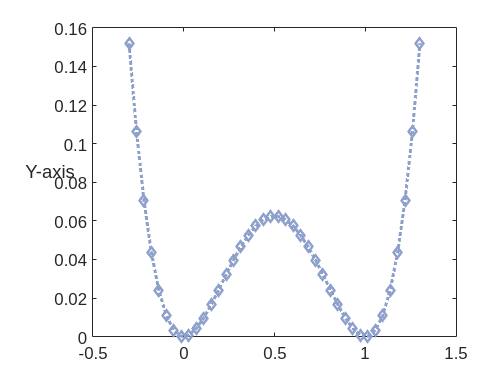

set(ax_1,'FontSize',14) %default is 10
set(lin_1,'Color','#8da0cb')
set(ax_1.YLabel,'string','Y-axis','Rotation',0)

## Subplots

As a reminder, you can make subplots in MATLAB using the subplots command. The usual format is `subplot(m,n,p)`, where *m and n* specify the dimesions (rows, columns) of the subplot grid, and *p* specifies the index of the plot.

fig_2 = figure

fig_2 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties

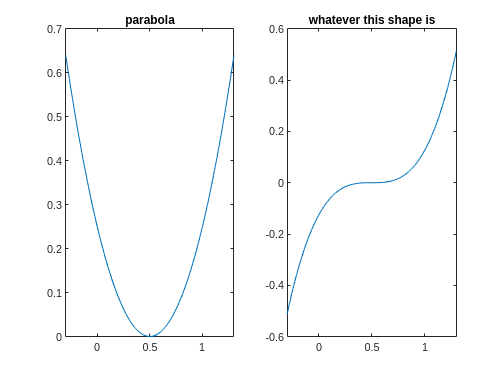

ax_2_1 = subplot(1,2,1);
ax_2_2 = subplot(1,2,2);

line_2_2 = plot(ax_2_1,x,(x-0.5).^2);
line_2_3 = plot(ax_2_2,x,(x-0.5).^3);

ax_2_1.Title.String = 'parabola'; %you can also set properties with assignment using =
ax_2_2.Title.String = 'whatever this shape is';

What some people don't know is that within the *m x n* subplot grid, you can assign a subplot to take on any arbitrary rectangular subsection of the grid by specifying the subplot-index of the top left portion and the bottom right portion. So, for a 3x4 grid, we could do:

fig_3 = figure;
ax_3_1 = subplot(3,4,1);
ax_3_2 = subplot(3,4,[6,11]);
ax_3_3 = subplot(3,4,[4,12])

ax_3_3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7484 0.1100 0.1566 0.8150]
            Units: 'normalized'

  Show all properties

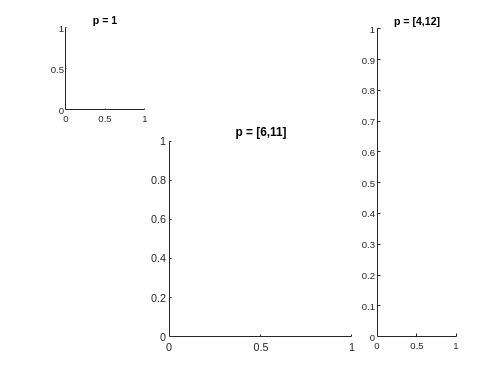

ax_3_1.Title.String='p = 1';
ax_3_2.Title.String='p = [6,11]';
ax_3_3.Title.String='p = [4,12]';

It's can be useful to note that the subplot grid is indexed by positive integers starting from the top left and going left-to-right, then down to the next row (the same as reading standard English). For example, for a 3x4 subplot, the indices are shown below:

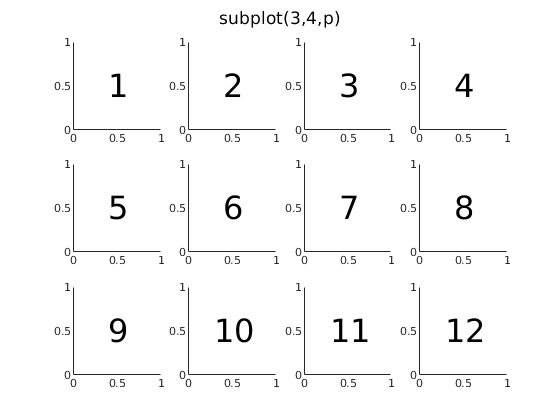

## Example: Group 14 Solids

Sean generated some internal energy (E) vs. unit cell volume (V) data for carbon, silicon, and germanium with DFT. First, we will import the datafiles, which are 2 x n arrays where the first column contains volumes (A^3) and the second row contains energy (eV).

Note: Raw energy values should not be directly compared as they do not share a well-defined reference point.

c_data = importdata('c_e_v.csv');
c_vol = c_data(:,1);
c_eng = c_data(:,2);

si_data = importdata('si_e_v.csv');
si_vol = si_data(:,1);
si_eng = si_data(:,2);

ge_data = importdata('ge_e_v.csv');
ge_vol = ge_data(:,1);
ge_eng = ge_data(:,2);

If we plot the energy volume curves, this is what we get:

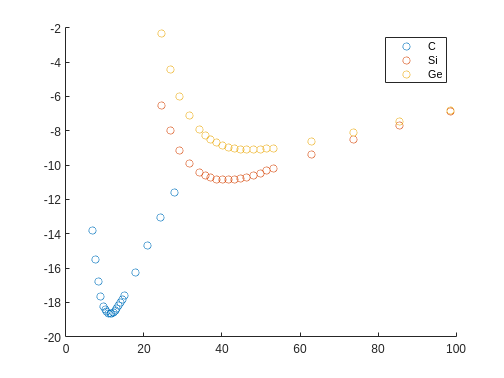

fig_4 = figure;
ax_4 = axes(fig_4);

scat_1 = scatter(ax_4,c_vol,c_eng);
hold on
scat_2 = scatter(ax_4,si_vol,si_eng);
scat_3 = scatter(ax_4,ge_vol,ge_eng);
legend('C','Si','Ge')

### Polynomial Fitting

We can fit a parabola near the equilibrium volumes:

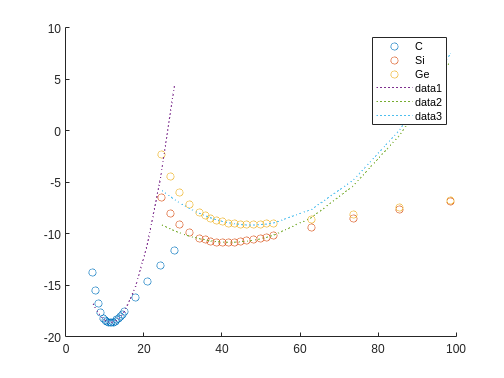

c_poly = polyfit(c_vol(5:17),c_eng(5:17),2); %polyfit is the tool of choice for fitting data to polynomials of arbitrary degree
si_poly = polyfit(si_vol(5:17),si_eng(5:17),2);
ge_poly = polyfit(ge_vol(5:17),ge_eng(5:17),2);

plot_1 = plot(ax_4,c_vol,polyval(c_poly,c_vol),':'); %the output of a polyfit is a vector of coefficients which can also easily be fed to polyval
plot_1 = plot(ax_4,si_vol,polyval(si_poly,si_vol),':');
plot_1 = plot(ax_4,ge_vol,polyval(ge_poly,ge_vol),':');

### Arbitrary Curve Fitting

The harmonic approximation is not very good far from equilibrium. We can do better and also extract physical parameters from this data by fitting to an equation of state. In this example, we fit to the Birch–Murnaghan equation of state:


$$E(V) = E_0 + \frac{9V_0B_0}{16} \left\{ \left[   \left(  \frac{V_0}{V}\right)^{\frac{2}{3}} - 1 \right]^3 B_0'  + \left[  \left(  \frac{V_0}{V}\right)^{\frac{2}{3}}-1 \right]^2 \left[ 6 - 4 \left(  \frac{V_0}{V}\right)^{\frac{2}{3}}    \right]    \right\}$$


The example below takes care of this by declaring a so-called "anonymous function", BMEq. In order to fit an arbitrary function in Matlab, the function's first input must be a vector of fitting coefficients, and the second input should be the x-data. In this case, the fitting parameters are E0, V0, B0, and B0', and the inputs to the function BMEq are defined as param (which willl be a vector containing all 4 of the coefficients), and v (which will be a vector of volume data).

BMEq = @(params, v) params(1) + (9*params(2)*params(3)/16) .* ...
    ( params(4).*(((params(2)./v).^(2/3) - 1)).^3 + ...
    (( (params(2)./(v)).^(2/3) -1 ).^2).* ...
    (6 - 4.*(params(2)./v).^(2/3)) );
%params(1) = E0
%params(2) = V0
%params(3) = B0
%params(4) = B0'

c_bmfit = lsqcurvefit(BMEq,[-19, 11, 5, 2],c_vol,c_eng);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


si_bmfit = lsqcurvefit(BMEq,[-10, 40, 5, 2],si_vol,si_eng);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ge_bmfit = lsqcurvefit(BMEq,[-10, 40, 5, 2],ge_vol,ge_eng);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


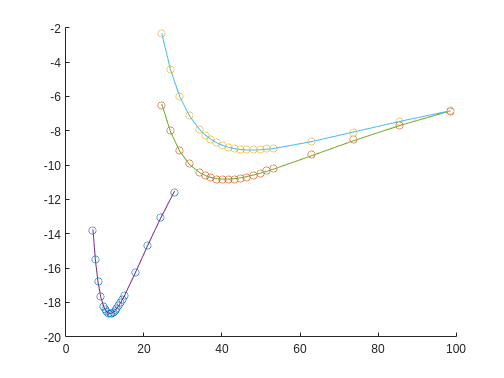

%lsqcurvefit requires a function handle, an initial guess at the fitting
%coefficients, the x data, and then the y data

fig_5 = figure;
ax_5 = axes(fig_5);
scat_1 = scatter(ax_5,c_vol,c_eng);
hold on
scat_2 = scatter(ax_5,si_vol,si_eng);
scat_3 = scatter(ax_5,ge_vol,ge_eng);

bm_1 = plot(ax_5,c_vol,BMEq(c_bmfit,c_vol));
bm_2 = plot(ax_5,si_vol,BMEq(si_bmfit,si_vol));
bm_3 = plot(ax_5,ge_vol,BMEq(ge_bmfit,ge_vol));

So far we've just created the most basic plots we can with this data and the fits. See if you can make these plots any nicer! Think about what you can communicate with this data and then try to make a clear and `a e s t h e t i c` plot.

Remember, the data you have to work with for each material (C, Si, Ge) is:

- Raw DFT energy-volume data (c_vol, c_eng, si_vol, si_eng, ge_vol, ge_eng)

- The Birch-Murnaghan equation of state and its fitted parameters, including bulk modulus (c_bmfit, si_bmfit, ge_bmfit)

- The quadratic fitting coefficients (c_poly, si_poly, ge_poly)

---

Some questions to get you thinking about what or how to make a good plot from this data:

- What are the quantities of interest?

- What do the fits show that the raw data doesn't?

- What do you want your audience to learn from your plot?

- How can you minimize the amount of thinking required on behalf of your audience in interpreting your plot; in other words, how can you make your plot efficient?

Once you have a visualization, ask yourself those questions again to see if you can find further ways to improve your plot. Here are a few more questions you can ask yourself:

- Is the feature or quantity you're trying to communicate the most obvious part of the plot?

- Are the colors visually distinct? What about to someone with colorblindness (red-green colorblindness is the most common type)?

- Does understanding your plot require frequent visual lookup (i.e. looking back and forth at the plot and a legend to make sense of the plot)?